## **Лабораторная работа №2**

**В момент времени***** t = 0***** волновая функция, описывающая квантовое состояние микрочастицы, движущейся вдоль оси *****x *****имеет вид:**


$$\psi \;\left(x,0\right)=A*e^{-\frac{x^2 }{a^2 }+\mathrm{ibx}}$$


**Здесь: A, a, b - известные действительные константы.**

**Определить зависимость от координаты***** x*****:**

**1) действительной части волновой функции**

**2) мнимой части волновой функции**

**3) квадрата модуля волновой зависимости**

**Построить эти зависимости.**

clc; clear;

ampl = 5;
A = 7/6*sqrt(2); B = 8/5*pi;

nOfPointsInner = 100;
nOfPointsFunc = 1000;

xInner = linspace(-5, 5, nOfPointsInner);
xFunc = linspace(-5, 5, nOfPointsFunc);

Здесь задаём коэффициенты функции, количество точек для просчитанной по формуле функции и встроенной функции MatLab, получаем вектора оси x

subplot(2,1,1);

realFunc = ampl * exp( - xFunc.^2 / A^2) .* cos(B*xFunc);
plot(xFunc, realFunc, 'b');
hold on;

realInner = real(countWave(xInner, ampl, A, B));
plot(xInner, realInner, 'r.');
grid on;

legend('Aexp(-x^2/a^2)*cos(b*x)', 'real(\psi (x))')
title('Действительная часть')

Вектор действительной части уравнения волны. Т.к. функция имеет мнимую единицу при одном слагаемом в экспоненте, мы можем разложить экспоненту на её произведения. А экспоненту с мнимой единицей по формуле Эйлера:


$$\begin{array}{l}
\psi \;\left(x,0\right)=A*e^{-\frac{x^2 }{a^2 }+\mathrm{ibx}} \\
\psi \;\left(x,0\right)=A*e^{-\frac{x^2 }{a^2 }} *e^{\mathrm{ibx}} \\
\psi \;\left(x,0\right)=A*e^{-\frac{x^2 }{a^2 }} *\left(\mathrm{cos}\left(\mathrm{bx}\right)+i*\mathrm{sin}\left(\mathrm{bx}\right)\right)\\
\psi \;\left(x,0\right)=A*e^{-\frac{x^2 }{a^2 }} *\mathrm{cos}\left(\mathrm{bx}\right)+i\;*A*e^{-\frac{x^2 }{a^2 }} *\mathrm{sin}\left(\mathrm{bx}\right)\\
\mathrm{real}\left(\psi \left(x,0\right)\right)=A*e^{-\frac{x^2 }{a^2 }} *\mathrm{cos}\left(\mathrm{bx}\right)\\
\mathrm{imag}\left(\psi \left(x,0\right)\right)=A*e^{-\frac{x^2 }{a^2 }} *\mathrm{sin}\left(\mathrm{bx}\right)
\end{array}$$


Таким образом получаем функции для нахождения действительной и мнимой части волны без встроенных matlab функций.

Для проверки добавляем тот же самый график, построенный через real() в виде точек. 

Добавляем заголовок и легенду.

subplot(2,1,2);

imagFunc = ampl * exp(- xFunc .^2 / A^2) .* sin(B*xFunc);
plot(xFunc, imagFunc, 'b');
hold on;

imagInner = imag(countWave(xInner, ampl, A, B));
plot(xInner, imagInner, 'r.');
hold on;

Аналогично действительной части, находим мнимую через встроенные средства и вручную.

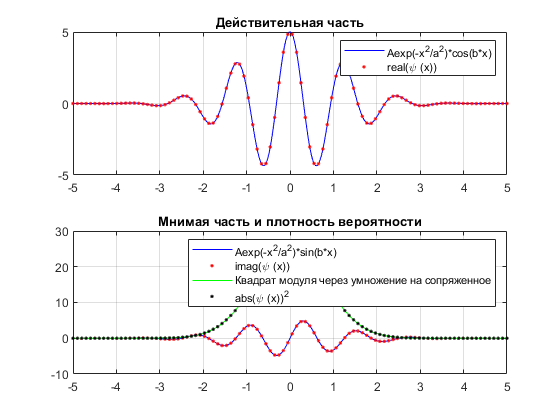

absFunc = (realFunc + 1i * imagFunc) .* (realFunc - 1i* imagFunc);
plot(xFunc, absFunc, 'g');
hold on;

absInner = abs(countWave(xInner, ampl, A, B)).^2;
plot(xInner, absInner, 'k.');
grid on;

legend('Aexp(-x^2/a^2)*sin(b*x)', 'imag(\psi (x))', 'Квадрат модуля через умножение на сопряженное', 'abs(\psi (x))^2')
title('Мнимая часть и плотность вероятности')

Для плотности вероятности достаточно переменожить уже имеющиеся сумму/разность мнимых и действительных коэффициентов (то есть методом умножения на сопряженное).

Аналогично находим плотность вероятности через встроенные средства. Заполняем легенду и название графика.

function Y = countWave(x, ampl, A, B)
    Y = ampl .* exp( -1 .* x .^ 2 ./ A^2 + 1i .* B .* x);
end

#### Вывод: определили зависимости плотности вероятности, действительной и мнимых частей от x. Нашли зависимости с помощью нескольких вариантов функционала Matlab'a.